Load model and control law

linearized_model;

A =          0         0    1.0000         0
         0         0         0    1.0000
         0   40.7056  -13.2363         0
         0    0.0760   -4.7195         0


B =          0
         0
   23.2996
    8.3076


C =      1     0     0     0
     0     1     0     0


D =      0
     0


lqr_control_law;

ss_system =
 
  A = 
            x1       x2       x3       x4
   x1        0        0        1        0
   x2        0        0        0        1
   x3        0    40.71   -13.24        0
   x4        0  0.07603    -4.72        0
 
  B = 
          u1
   x1      0
   x2      0
   x3   23.3
   x4  8.308
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.



Q =     1.0000         0         0         0
         0    8.0000         0         0
         0         0    0.1000         0
         0         0         0    1.0000


R = 0.8000

K =     1.1180    7.3074    0.3543    0.1124


S =     0.8250    0.1005    0.1612   -0.3445
    0.1005   14.1080    0.4274   -0.4949
    0.1612    0.4274    0.1306   -0.3322
   -0.3445   -0.4949   -0.3322    0.9425


P =   -1.0677 + 3.2942i
  -1.0677 - 3.2942i
  -1.6859 + 0.0000i
 -18.6028 + 0.0000i


Controlability

poles = eigs(A-B*K) % system is stable

poles =  -18.6028 + 0.0000i
  -1.0677 + 3.2942i
  -1.0677 - 3.2942i
  -1.6859 + 0.0000i


Create steady state model with control law

ss_system = ss(A-B*K, B, C, D)

ss_system =
 
  A = 
            x1       x2       x3       x4
   x1        0        0        1        0
   x2        0        0        0        1
   x3   -26.05   -129.6   -21.49   -2.618
   x4   -9.288   -60.63   -7.663  -0.9335
 
  B = 
          u1
   x1      0
   x2      0
   x3   23.3
   x4  8.308
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.



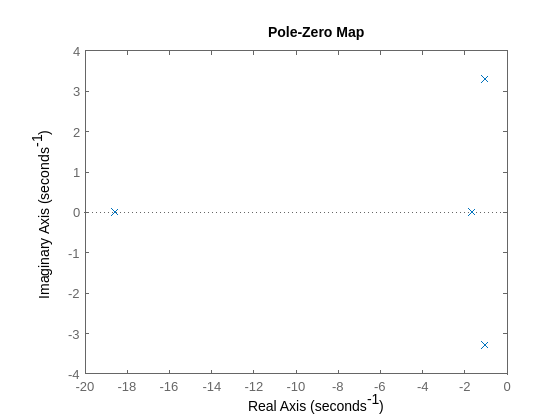

pzplot(ss_system)

Step response

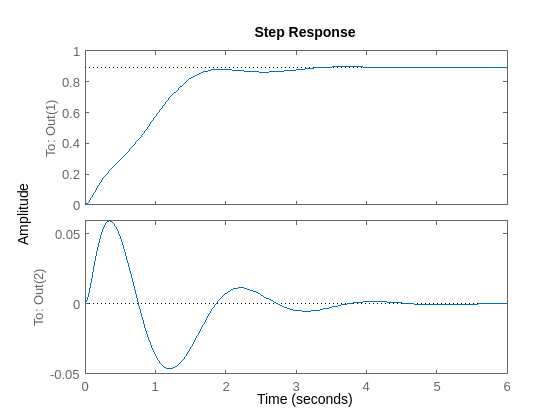

step(ss_system)

Impulse response

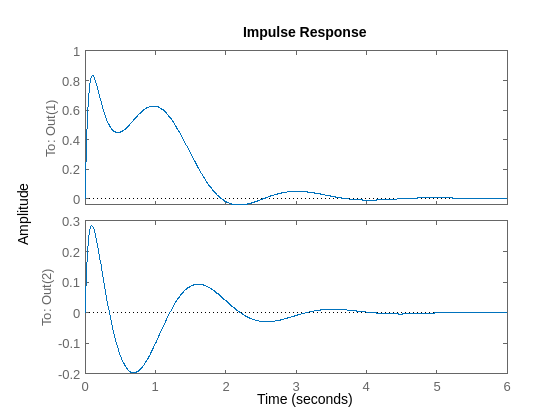

impulse(ss_system)

Response for initial conditions

closed_loop_system = ss(A-B*K, [0; 0; 0; 0], C, D)

closed_loop_system =
 
  A = 
            x1       x2       x3       x4
   x1        0        0        1        0
   x2        0        0        0        1
   x3   -26.05   -129.6   -21.49   -2.618
   x4   -9.288   -60.63   -7.663  -0.9335
 
  B = 
       u1
   x1   0
   x2   0
   x3   0
   x4   0
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.




%x_init = [pi/2; 0; 0; 0;]
%initial(closed_loop_system, x_init)

Responses to rod disturbance

x_init = [0; pi/90; 0; 0;]

x_init =          0
    0.0349
         0
         0


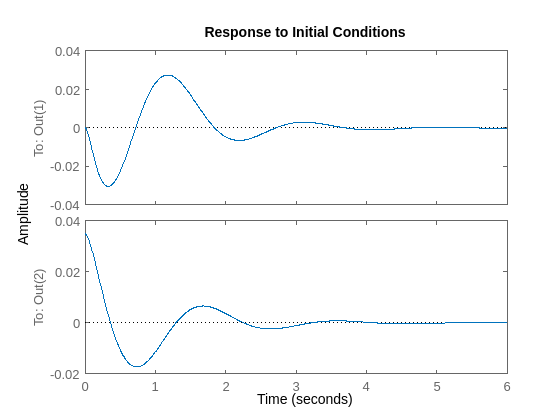

initial(closed_loop_system, x_init)